Consider the following example studied in [1]

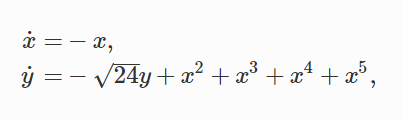

We take the first mode as master mode and calculate the SSM using graphstyle. The reduced dynamics is already linear and the expansion will be of the following


$$y=h(x)=a_2x^2+a_3x^3+a_4x^4+a_5x^5+\cdots$$


where


$$a_2=\frac{1}{\sqrt{24}-2}, a_3=\frac{1}{\sqrt{24}-3}, a_4=\frac{1}{\sqrt{24}-4}, a_5=\frac{1}{\sqrt{24}-5},a_j=0,j\geq6$$


[1] Haller, G., & Ponsioen, S. (2016). Nonlinear normal modes and spectral submanifolds: existence, uniqueness and use in model reduction. *Nonlinear dynamics*, *86*(3), 1493-1534.

clear all;
[A,B,F] = build_model();

## Dynamical system setup

DSorder = 1;
DS = DynamicalSystem(DSorder);
set(DS,'A',A,'B',B,'fnl',F);
set(DS.Options,'Emax',2,'Nmax',10,'notation','tensor');
% set(DS.Options,'Emax',2,'Nmax',10,'notation','multiindex')

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();


 The first 2 eigenvalues are given as 
   -1.0000
   -4.8990



S = SSM(DS);
set(S.Options,'paramStyle','graph')
% set(S.Options, 'reltol', 10,'notation','multiindex')
set(S.Options, 'reltol', 10,'notation','tensor')
masterModes = 1; % single mode will fail 
order = 8;
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     2
     3
     4

These are in resonance with the follwing eigenvalues of the slave subspace
   -4.8990
   -4.8990
   -4.8990

sigma_out = 4
(near) inner resonance detected for the following combination of master eigenvalues
     2
     3
     4

These are in resonance with the follwing eigenvalues of the master subspace
    -1
    -1
    -1

sigma_in = 4


[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.30E-03 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 8.92E-03 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.03E-02 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.17E-02 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computatio

One can then check the correctness of the results.